g = 9.82;
m = 1.513;
Ixx = 0.0185; 
Iyy = 0.0201;
Izz = 0.0286;
Kt = 0.011;
lroll = 0.175;
lpitch = 0.175;
Km = 327e-6;

A = [zeros(6,6)  [0 0 0 0 g 0; 0 0 0 -g 0 0 ; zeros(4,6)];
    eye(6) zeros(6,6)];
B = [zeros(4,2) [Kt/m -(lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) (Km)/(Izz); Kt/m (lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) -(Km)/(Izz); Kt/m (lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) (Km)/(Izz); Kt/m -(lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) -(Km)/(Izz);] zeros(4,6)].';
% C = [0 0 0 0 0 0 1 0 0 0 0 0 ;
%      0 0 0 0 0 0 0 1 0 0 0 0 ;
%      0 0 0 0 0 0 0 0 1 0 0 0 ;
%      0 0 0 0 0 0 0 0 0 1 0 0 ;
%      0 0 0 0 0 0 0 0 0 0 1 0 ;
%      0 0 0 0 0 0 0 0 0 0 0 1 ;];
C = eye(12);
D = zeros(12,4);

SSModel = ss(A,B,C,D)

SSModel =
 
  A = 
           x1     x2     x3     x4     x5     x6     x7     x8     x9    x10    x11    x12
   x1       0      0      0      0      0      0      0      0      0      0   9.82      0
   x2       0      0      0      0      0      0      0      0      0  -9.82      0      0
   x3       0      0      0      0      0      0      0      0      0      0      0      0
   x4       0      0      0      0      0      0      0      0      0      0      0      0
   x5       0      0      0      0      0      0      0      0      0      0      0      0
   x6       0      0      0      0      0      0      0      0      0      0      0      0
   x7       1      0      0      0      0      0      0      0      0      0      0      0
   x8       0      1      0      0      0      0      0      0      0      0      0      0
   x9       0      0      1      0      0      0      0      0      0      0      0      0
   x10      0      0      0      1      0      0      0      0      0  


controllability = rank(ctrb(A,B))

controllability = 12

observability = rank(obsv(A,C))

observability = 12


t = 0:1:60

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


u = [ones(4,1) zeros(4,length(t)-1)]

u =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

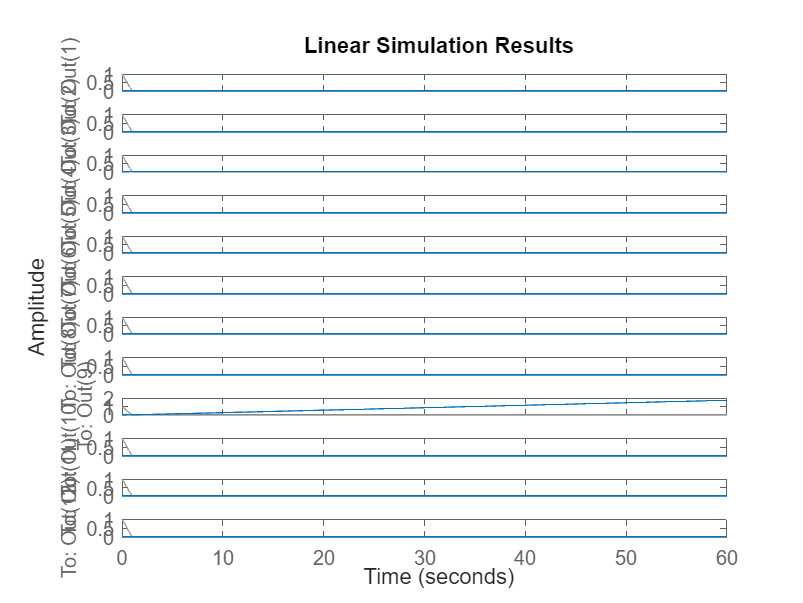

lsim(SSModel, u,t)



s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties



G = C/(s*eye(12)-A)*B

G =
 
  From input 1 to output...
                         -0.9405
   1:  -------------------------------------------
       s^3 + 3.126e-16 s^2 - 3.173e-16 s - 1.2e-19
 
                           1.022
   2:  ---------------------------------------------
       s^3 - 1.282e-15 s^2 + 5.679e-16 s - 6.627e-19
 
       0.00727
   3:  -------
          s
 
       -0.1041
   4:  -------
          s
 
       -0.09577
   5:  --------
          s
 
       0.01143
   6:  -------
          s
 
                                  -0.9405
   7:  -------------------------------------------------------------
       s^4 - 2.916e-16 s^3 - 2.524e-16 s^2 + 3.825e-17 s + 2.152e-17
 
                                  1.022
   8:  ------------------------------------------------------------
       s^4 - 4.736e-16 s^3 + 2.715e-16 s^2 + 2.06e-17 s - 6.391e-18
 
                  0.00727
   9:  -----------------------------
       s^2 + 2.071e-16 s - 2.208e-33
 
                   -0.1041
   10:  -------------

G(1,1)

ans =
 
                    -0.9405
  -------------------------------------------
  s^3 + 3.126e-16 s^2 - 3.173e-16 s - 1.2e-19
 
Continuous-time transfer function.
Model Properties



G(7,1)

ans =
 
                             -0.9405
  -------------------------------------------------------------
  s^4 - 2.916e-16 s^3 - 2.524e-16 s^2 + 3.825e-17 s + 2.152e-17
 
Continuous-time transfer function.
Model Properties
